% Initialize random number generator
rng(2025)

% Create terrain
xLimits         = [900 1200]; % x-axis limits of terrain (m)
yLimits         = [-200 200]; % y-axis limits of terrain (m)
roughnessFactor = 1.75;       % Roughness factor
initialHgt      = 0;          % Initial height (m)
initialPerturb  = 200;        % Overall height of map (m) 
numIter         = 8;          % Number of iterations
[x,y,A] = helperRandomTerrainGenerator(roughnessFactor,initialHgt, ....
    initialPerturb,xLimits(1),xLimits(2), ...
    yLimits(1),yLimits(2),numIter);
A(A < 0) = 0; % Fill-in areas below 0
xvec = x(1,:); 
yvec = y(:,1);
resMapX = mean(diff(xvec))

resMapX = 1.1719


resMapY = mean(diff(yvec))

resMapY = 1.5625

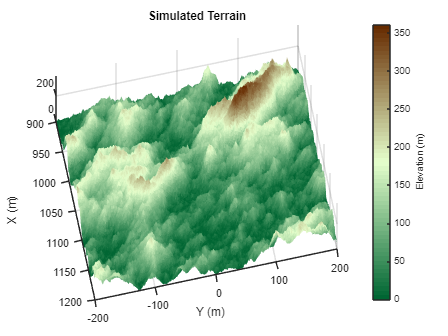

% Plot simulated terrain
helperPlotSimulatedTerrain(xvec,yvec,A)



% Define key radar parameters
freq = 1e9;                        % Carrier frequency (Hz)
[lambda,c] = freq2wavelen(freq);   % Wavelength (m) 
bw = 30e6;                         % Signal bandwidth (Hz)
fs = 60e6;                         % Sampling frequency (Hz)
tpd = 3e-6;                        % Pulse width (sec) 

% Verify that the range resolution is as expected
rngRes = bw2rangeres(bw)

rngRes = 4.9965



% Antenna properties
apertureLength = 6;                % Aperture length (m) 
sqa = 0;                           % Squint angle (deg)


% Platform properties
v = 100;                           % Speed of the platform (m/s) 
dur = 1;                           % Duration of flight (s) 
rdrhgt = 1000;                     % Height of platform (m) 
rdrpos1 = [0 0 rdrhgt];            % Start position of the radar (m)
rdrvel = [0 v 0];                  % Radar plaform velocity
rdrpos2 = rdrvel*dur + rdrpos1;    % End position of the radar (m)
len = sarlen(v,dur)                % Synthetic aperture length (m)

len = 100


% Configure the target platforms in x and y
targetpos = [1000,len/2,0;1020,len/2,0;1040,len/2,0]; % Target positions (m)
tgthgts = 110*ones(1,3); % Target height (m)
for it = 1:3 
    % Set target height relative to terrain
    [~,idxX] = min(abs(targetpos(it,1) - xvec)); 
    [~,idxY] = min(abs(targetpos(it,2) - yvec)); 
    tgthgts(it) = tgthgts(it) + A(idxX,idxY); 
    targetpos(it,3) = tgthgts(it); 
end


% Set the reference slant range for the cross-range processing
rc = sqrt((rdrhgt - mean(tgthgts))^2 + (mean(targetpos(:,1)))^2);

% Antenna orientation
depang = depressionang(rdrhgt,rc,'Flat','TargetHeight',mean(tgthgts)); % Depression angle (deg)
grazang = depang; % Grazing angle (deg)

% Azimuth resolution
azResolution = sarazres(rc,lambda,len)  % Cross-range resolution (m)

azResolution = 2.0044


% Determine PRF bounds 
[swlen,swwidth] = aperture2swath(rc,lambda,apertureLength,grazang);
[prfmin,prfmax] = sarprfbounds(v,azResolution,swlen,grazang)

prfmin = 49.8907

prfmax = 6.5539e+05

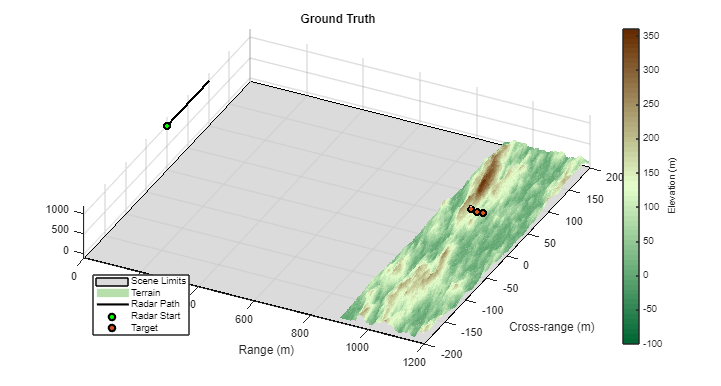



% Select a PRF within the PRF bounds
prf = 500; % Pulse repetition frequency (Hz)


% Create a radar scenario
scene = radarScenario('UpdateRate',prf,'IsEarthCentered',false,'StopTime',dur);

% Add platforms to the scene using the configurations previously defined 
rdrplat = platform(scene,'Trajectory',kinematicTrajectory('Position',rdrpos1,'Velocity',[0 v 0]));

% Add target platforms
rcs = rcsSignature('Pattern',5); 
for it = 1:3
    platform(scene,'Position',targetpos(it,:),'Signatures',{rcs});
end

% Plot ground truth
helperPlotGroundTruth(xvec,yvec,A,rdrpos1,rdrpos2,targetpos)

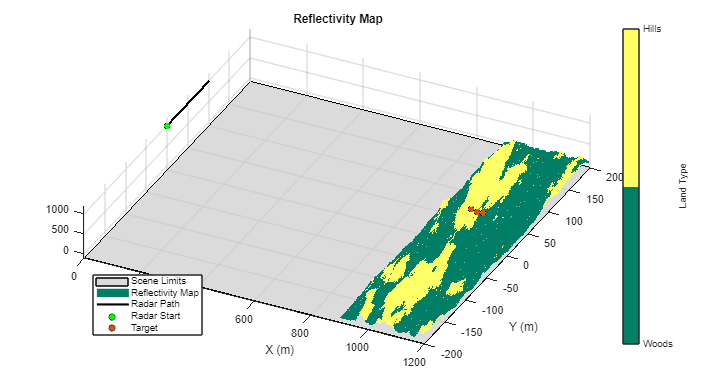


% Specify custom reflectivity map
grazTable = 20:0.1:60;
freqTable = [1e9 10e9]; 
numSurfaces = 2;
reflectivityLayers = zeros(numel(grazTable),numel(freqTable),numSurfaces);
reflectivityLayers(:,:,1) = landreflectivity('Woods', ...
    grazTable,freqTable);
reflectivityLayers(:,:,2) = landreflectivity('WoodedHills', ...
    grazTable,freqTable);
reflectivityType = ones(size(A)); 
reflectivityType(A > 100) = 2; 

% Plot custom reflectivity map
helperPlotReflectivityMap(xvec,yvec,A,reflectivityType,rdrpos1,rdrpos2,targetpos)


reflectivityMap = surfaceReflectivity('Custom','Frequency',freqTable, ...
    'GrazingAngle',grazTable,'Reflectivity',reflectivityLayers, ...
    'Speckle','Rayleigh')

reflectivityMap =   surfaceReflectivityCustom with properties:

    EnablePolarization: 0
          Reflectivity: [401×2×2 double]
             Frequency: [1.0000e+09 1.0000e+10]
          GrazingAngle: [20 20.1000 20.2000 20.3000 20.4000 20.5000 20.6000 20.7000 20.8000 20.9000 21 21.1000 21.2000 21.3000 21.4000 21.5000 21.6000 21.7000 21.8000 21.9000 22 22.1000 22.2000 22.3000 22.4000 22.5000 22.6000 22.7000 … ] (1×401 double)
               Speckle: 'Rayleigh'
          SpeckleScale: 0.7979


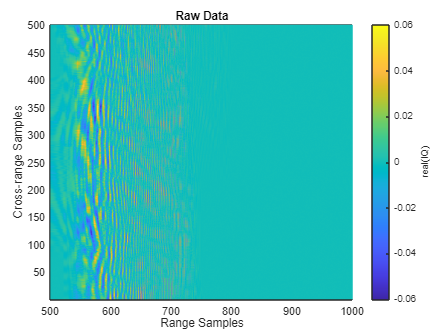


% Add land surface to scene
s = landSurface(scene,'Terrain',A,'Boundary',[xLimits;yLimits], ...
    'RadarReflectivity',reflectivityMap, ...
    'ReflectivityMap',reflectivityType);

% Create a radar looking to the right
maxRange = 2500; % Maximum range for IQ collection
mountAngles = [0 depang 0];
rdr = radarTransceiver('MountingAngles',mountAngles,'NumRepetitions',1, ...
    'RangeLimits',[0 maxRange]);

% Set peak power
rdr.Transmitter.PeakPower = 50e3; 

% Set receiver sample rate and noise figure
rdr.Receiver.SampleRate = fs;
rdr.Receiver.NoiseFigure = 30; 

% Define transmit and receive antenna and corresponding parameters
antbw = ap2beamwidth(apertureLength,lambda); 
ant = phased.SincAntennaElement('FrequencyRange',[1e9 10e9],'Beamwidth',antbw);
rdr.TransmitAntenna.Sensor = ant;
rdr.TransmitAntenna.OperatingFrequency = freq;
rdr.ReceiveAntenna.Sensor = ant;
rdr.ReceiveAntenna.OperatingFrequency = freq;
antennaGain = aperture2gain(apertureLength^2,lambda); 
rdr.Transmitter.Gain = antennaGain;
rdr.Receiver.Gain = antennaGain;

% Configure the LFM signal of the radar
rdr.Waveform = phased.LinearFMWaveform('SampleRate',fs,'PulseWidth',tpd, ...
    'PRF',prf,'SweepBandwidth',bw); 

% Add radar to radar platform
rdrplat.Sensors = rdr;

% Collect clutter returns with the clutterGenerator
clutterGenerator(scene,rdr,'Resolution',rngRes/2, ...
    'RangeLimit',maxRange);

% Initialize output IQ datacube
minSample = 500; % Minimum sample range
truncRngSamp = ceil(range2time(maxRange)*fs); % Limit the number of samples
T = 1/prf; % Pulse repetition interval (sec)
numPulses = dur/T + 1; % Number of pulses 
raw = zeros(numel(minSample:truncRngSamp),numPulses); % IQ datacube 

% Collect IQ 
ii = 1; 
hRaw = helperPlotRawIQ(raw,minSample);
simulateData = false; % Change to true to simulate IQ
if simulateData
    while advance(scene) %#ok<UNRCH>
        tmp = receive(scene); % nsamp x 1
        raw(:,ii) = tmp{1}(minSample:truncRngSamp);
        if mod(ii,100) == 0 % Update plot after 100 pulses
            helperUpdatePlotRawIQ(hRaw,raw);
        end
        ii = ii + 1;
    end
else
    load('rawSAR.mat');
end
helperUpdatePlotRawIQ(hRaw,raw);

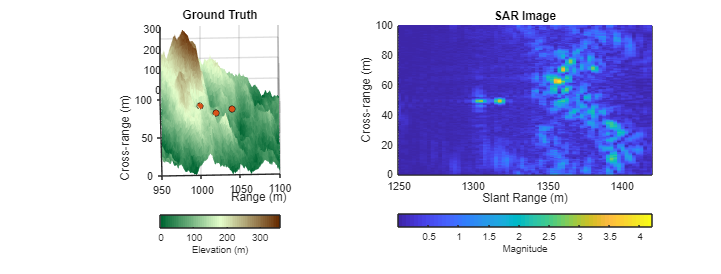



% Generating Single Look Complex image using range migration algorithm
slcimg = rangeMigrationLFM(raw,rdr.Waveform,freq,v,rc);
helperPlotSLC(slcimg,minSample,fs,v,prf,rdrpos1,targetpos, ...
    xvec,yvec,A)


for it = 1:3
    % Determine whether the target was occluded
    occ = false(1,numPulses); 
    for ip = 1:numPulses
        rdrpos = rdrpos1 + rdrvel.*1/prf*(ip - 1); 
        occ(ip) = s.occlusion(rdrpos,targetpos(it,:));
    end

    % Translate occlusion values to a visibility status
    helperGetVisibilityStatus(it,occ)
end

Target 1 is not visible during the scenario (visible 0% of the data collection).
Target 2 is not visible during the scenario (visible 0% of the data collection).
Target 3 is not visible during the scenario (visible 0% of the data collection).


function [x,y,terrain] = helperRandomTerrainGenerator(f,initialHeight, ...
    initialPerturb,minX,maxX,minY,maxY,numIter)
%randTerrainGenerator Generate random terrain
% [x,y,terrain] = helperRandomTerrainGenerator(f,initialHeight, ...
%    initialPerturb,minX,maxX,minY,maxY,seaLevel,numIter)
%
% Inputs: 
%   - f                   = A roughness parameter.  A factor of 2 is a
%                           typical default. Lower values result in a 
%                           rougher terrain; higher values result in a 
%                           smoother surface.
%   - initialHeight       = Sets the initial height of the lattice before 
%                           the perturbations.
%   - initialPerturb      = Initial perturbation amount. This sets the 
%                           overall height of the landscape.
%   - minX,maxX,minY,maxY = Initial points. Provides some degree of control
%                           over the macro appearance of the landscape.
%   - numIter             = Number of iterations that affects the density 
%                           of the mesh that results from the iteration
%                           process.
%
% Output: 
%    - x                  = X-dimension mesh grid
%    - y                  = Y-dimension mesh grid
%    - terrain            = Two-dimensional array in which each value 
%                           represents the height of the terrain at that 
%                           point/mesh-cell

% Generate random terrain
dX = (maxX-minX)/2;
dY = (maxY-minY)/2;
[x,y] = meshgrid(minX:dX:maxX,minY:dY:maxY);
terrain = ones(3,3)*initialHeight;
perturb = initialPerturb;
for ii = 2:numIter
    perturb = perturb/f;
    oldX = x;
    oldY = y;
    dX = (maxX-minX)/2^ii;
    dY = (maxY-minY)/2^ii;
    [x,y] = meshgrid(minX:dX:maxX,minY:dY:maxY);
    terrain = griddata(oldX,oldY,terrain,x,y);
    terrain = terrain + perturb*randn(1+2^ii,1+2^ii);
    terrain(terrain < 0) = 0; 
end
end

function cmap = landColormap(n)
%landColormap Colormap for land surfaces
% cmap = landColormap(n)
%
% Inputs: 
%    - n     = Number of samples in colormap
%
% Output: 
%    - cmap  = n-by-3 colormap

c = hsv2rgb([5/12 1 0.4; 0.25 0.2 1; 5/72 1 0.4]);
cmap = zeros(n,3);
cmap(:,1) = interp1(1:3,c(:,1),linspace(1,3,n)); 
cmap(:,2) = interp1(1:3,c(:,2),linspace(1,3,n));
cmap(:,3) = interp1(1:3,c(:,3),linspace(1,3,n)); 
colormap(cmap);
end

function helperPlotSimulatedTerrain(xvec,yvec,A)
% Plot simulated terrain

figure()
hS = surf(xvec,yvec,A);
hS.EdgeColor = 'none';
hC = colorbar;
hC.Label.String = 'Elevation (m)';
landmap = landColormap(64);
colormap(landmap); 
xlabel('X (m)')
ylabel('Y (m)')
axis equal;
title('Simulated Terrain')
view([78 78])
drawnow
pause(0.25)
end

function helperPlotGroundTruth(xvec,yvec,A,rdrpos1,rdrpos2,targetpos)
% Plot ground truth

f = figure('Position',[505 443 997 535]);
movegui(f,'center');
% Plot boundary. Set plot boundary much lower than 0 for rendering reasons. 
hLim = surf([0 1200],[-200 200].',-100*ones(2),'FaceColor',[0.8 0.8 0.8],'FaceAlpha',0.7);
hold on;
hS = surf(xvec,yvec,A);
hS.EdgeColor = 'none';
hC = colorbar;
hC.Label.String = 'Elevation (m)';
landmap = landColormap(64);
colormap(landmap); 
hPlatPath = plot3([rdrpos1(1) rdrpos2(1)], ...
    [rdrpos1(2) rdrpos2(2)],[rdrpos1(3) rdrpos2(3)], ...
    '-k','LineWidth',2);
hPlatStart = plot3(rdrpos1(1),rdrpos1(2),rdrpos1(3), ...
    'o','LineWidth',2,'MarkerFaceColor','g','MarkerEdgeColor','k');
hTgt = plot3(targetpos(:,1),targetpos(:,2),targetpos(:,3), ...
    'o','LineWidth',2,'MarkerFaceColor',[0.8500 0.3250 0.0980], ...
    'MarkerEdgeColor','k');
view([26 75])
xlabel('Range (m)')
ylabel('Cross-range (m)')
title('Ground Truth')
axis tight;
zlim([-100 1200])
legend([hLim,hS,hPlatPath,hPlatStart,hTgt], ...
    {'Scene Limits','Terrain','Radar Path','Radar Start','Target'},'Location','SouthWest')
drawnow
pause(0.25)
end

function helperPlotReflectivityMap(xvec,yvec,A,reflectivityType,rdrpos1,rdrpos2,targetpos)
% Plot custom reflectivity map

f = figure('Position',[505 443 997 535]);
movegui(f,'center');
% Plot boundary. Set plot boundary much lower than 0 for rendering reasons. 
hLim = surf([0 1200],[-200 200].',-100*ones(2),'FaceColor',[0.8 0.8 0.8],'FaceAlpha',0.7);
hold on
hS = surf(xvec,yvec,A,reflectivityType);
hS.EdgeColor = 'none';
hold on;
colormap(summer(2));
hC = colorbar;
clim([1 2]); 
hC.Ticks = [1 2];
hC.TickLabels = {'Woods','Hills'};
hC.Label.String = 'Land Type';
hPlatPath = plot3([rdrpos1(1) rdrpos2(1)],[rdrpos1(2) rdrpos2(2)],[rdrpos1(3) rdrpos2(3)], ...
    '-k','LineWidth',2);
hPlatStart = plot3(rdrpos1(1),rdrpos1(2),rdrpos1(3), ...
    'o','MarkerFaceColor','g','MarkerEdgeColor','k');
hTgt = plot3(targetpos(:,1),targetpos(:,2),targetpos(:,3), ...
    'o','MarkerFaceColor',[0.8500 0.3250 0.0980],'MarkerEdgeColor','k');
view([26 75])
xlabel('X (m)')
ylabel('Y (m)')
title('Reflectivity Map')
axis tight; 
zlim([-100 1200])
legend([hLim,hS,hPlatPath,hPlatStart,hTgt], ...
    {'Scene Limits','Reflectivity Map','Radar Path','Radar Start','Target'},'Location','SouthWest')
drawnow
pause(0.25)
end

function hRaw = helperPlotRawIQ(raw,minSample)
% Plot real of raw SAR IQ 

figure()
[m,n] = size(raw); 
hRaw = pcolor(minSample:(m + minSample - 1),1:n,real(raw.'));
hRaw.EdgeColor = 'none';
title('Raw Data')
xlabel('Range Samples')
ylabel('Cross-range Samples')
hC = colorbar;
clim([-0.06 0.06])
hC.Label.String = 'real(IQ)'; 
drawnow
pause(0.25)
end

function helperUpdatePlotRawIQ(hRaw,raw)
% Update the raw SAR IQ plot

hRaw.CData = real(raw.'); 
clim([-0.06 0.06]);
drawnow
pause(0.25)
end

function helperPlotSLC(slcimg,minSample,fs,v,prf,rdrpos1,targetpos, ...
    xvec,yvec,A)
% Plot magnitude of focused SAR image alongside reflectivity map

% Cross-range y-vector (m)
numPulses = size(slcimg,2); 
du = v*1/prf; % Cross-range sample spacing (m) 
dky = 2*pi/(numPulses*du); % ku domain sample spacing (rad/m)
dy = 2*pi/(numPulses*dky); % y-domain sample spacing (rad/m)
y = dy*(0:(numPulses - 1)) + rdrpos1(2); % Cross-range y-vector (m) 

% Range vector (m)
c = physconst('LightSpeed'); 
numSamples = size(slcimg,1); 
samples = minSample:(numSamples + minSample - 1);
sampleTime = samples*1/fs; 
rngVec = time2range(sampleTime(1:end),c); 

% Initialize figure
f = figure('Position',[264 250 1411 535]);
movegui(f,'center')
tiledlayout(1,2,'TileSpacing','Compact');

% Ground Truth
nexttile;
hS = surf(xvec,yvec,A);
hS.EdgeColor = 'none';
hold on;
plot3(targetpos(:,1),targetpos(:,2),targetpos(:,3), ...
    'o','MarkerFaceColor',[0.8500 0.3250 0.0980],'MarkerEdgeColor','k');
landmap = landColormap(64);
colormap(landmap); 
hC = colorbar('southoutside');
hC.Label.String = 'Elevation (m)';
view([-1 75])
xlabel('Range (m)')
ylabel('Cross-range (m)')
title('Ground Truth')
axis equal
xlim([950 1100])
ylim([0 100])

% SAR Image
nexttile; 
slcimg = abs(slcimg).';
hProc = pcolor(rngVec,y,slcimg);
hProc.EdgeColor = 'none'; 
colormap(hProc.Parent,parula)
hC = colorbar('southoutside');
hC.Label.String = 'Magnitude';
xlabel('Slant Range (m)')
ylabel('Cross-range (m)')
title('SAR Image')
axis equal
xlim([1250 1420])
ylim([0 100])

drawnow
pause(0.25)
end

function helperGetVisibilityStatus(tgtNum,occ)
% Translate occlusion values to a visibility status

visibility = {'not','partially','fully'};
if all(occ)
    idx = 1;
elseif any(occ)
    idx = 2;
else
    idx = 3;
end
visString = visibility{idx};
pctCollect = sum(double(~occ))./numel(occ)*100;
fprintf('Target %d is %s visible during the scenario (visible %.0f%% of the data collection).\n', ...
    tgtNum,visString,pctCollect)
drawnow
pause(0.25)
end